# Statics Truss Solver - UMass Amherst CE-ENGIN 240 Statics - Egemen Okte

The following code solves trusses that are determinate using method of joints. You can define nodes, edges (members), supports and loads and plot/solve the truss system. 

## Example 1

First, define the truss structure and display it. You must define nodes, edges (members), support conditions (pin or roller) and the loads on nodes.

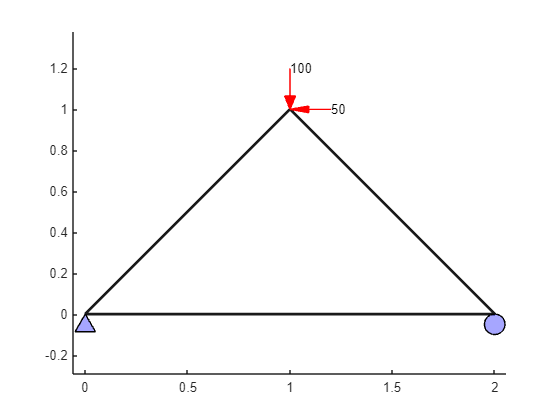

clear;clc;close all;warning('off') 

% Define nodes coordinates (x, y)
nodes = [0,0 ; 1,1 ; 2,0];  % Each row represents a node

% Define edges (member connectivity)
edges = [1,2 ; 2,3 ; 1,3];  % Each row represents a member with start and end node

% Define support conditions (1 if restrained, 0 if free) [u_x, u_y; ...]
supports = [1, 1; 0, 0; 0, 1];  % Assuming pin supports at node 1 and roller at node 3

% Define nodal loads [F_x, F_y; ...]
loads = [0, 0; -50, -100; 0, 0];  % Assuming a downward load at node 2

plottruss(nodes,edges,supports,loads,[]); %Plot the truss member

Then solve for the member forces/reactions and display them on the members/supports

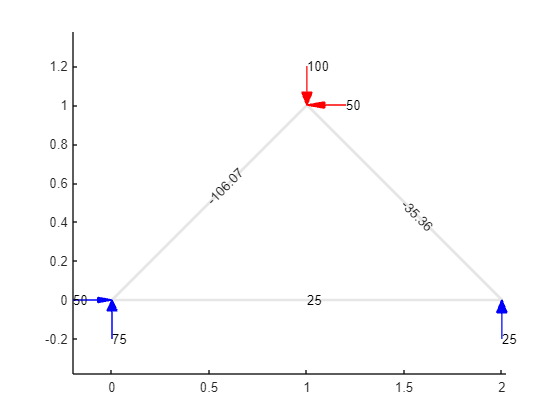

%Solve the truss member
forces=solvetruss(nodes,edges,supports,loads);
close all;
plottruss(nodes,edges,supports,loads,forces);

## Example 2

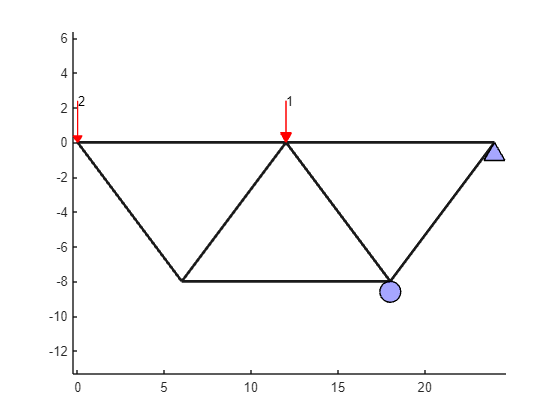

close all;
% Define nodes coordinates (x, y)
nodes = [0,0 ; 6,-8 ; 12,0 ; 18,-8 ; 24,0]; % Each row represents a node

% Define edges (member connectivity)
edges = [1,2 ; 1,3 ; 2,3 ; 2,4 ; 3,4; 3,5 ; 4,5];  % Each row represents a member with start and end node

% Define support conditions (1 if restrained, 0 if free) [u_x, u_y; ...]
supports = [0,0 ; 0,0; 0,0; 0,1 ; 1,1];   

% Define nodal loads [F_x, F_y; ...]
loads = [0,-2 ; 0,0; 0,-1; 0,0 ; 0,0];    

plottruss(nodes,edges,supports,loads,[]);

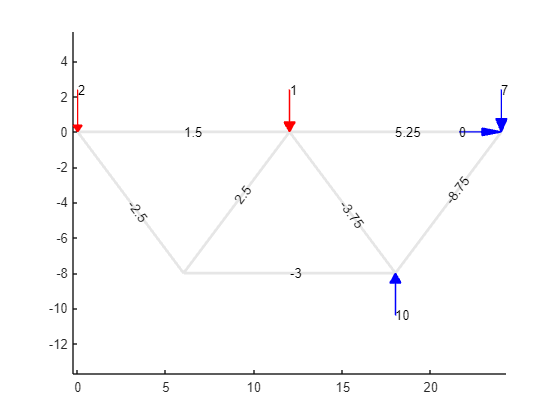

%Solve the truss member
forces=solvetruss(nodes,edges,supports,loads);
close all;
plottruss(nodes,edges,supports,loads,forces);

## Example 3

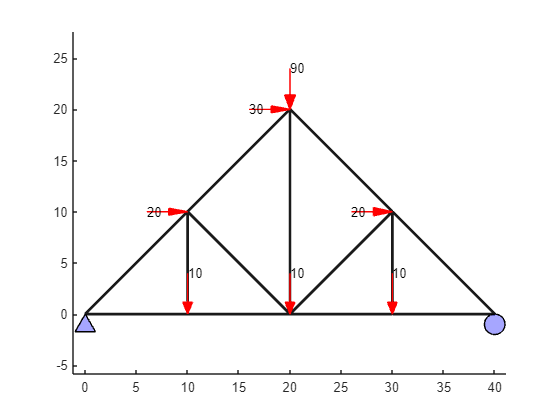

close all;
% Define nodes coordinates (x, y)
nodes = [0,0 ; 10,0 ; 20,0 ; 30,0 ; 40,0 ; 10,10 ; 20,20 ; 30,10]; % Each row represents a node

% Define edges (member connectivity)
edges = [1,2 ; 2,3 ; 3,4 ; 4,5 ; 1,6; 2,6 ; 3,6 ; 6,7 ; 3,7 ; 7,8 ; 3,8 ; 4,8 ; 5,8 ];  % Each row represents a member with start and end node

% Define support conditions (1 if restrained, 0 if free) [u_x, u_y; ...]
supports = [1,1 ; 0,0 ; 0,0 ; 0,0 ; 0,1 ; 0,0 ; 0,0 ; 0,0];  

% Define nodal loads [F_x, F_y; ...]
loads = [0,0 ; 0,-10 ; 0,-10 ; 0,-10 ; 0,0 ; 20,0 ; 30,-90 ; 20,0];     

plottruss(nodes,edges,supports,loads,[]);

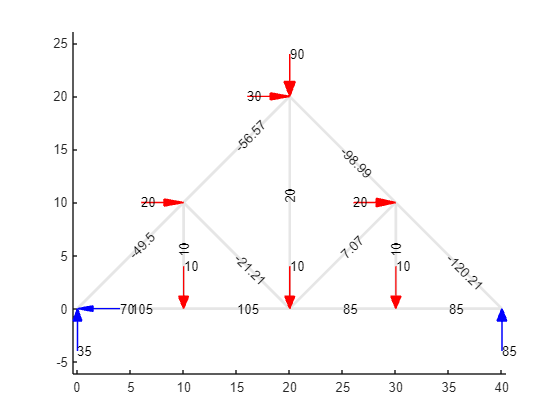

%Solve the truss member
forces=solvetruss(nodes,edges,supports,loads);
close all;
plottruss(nodes,edges,supports,loads,forces);